load("AttitudeOpenLoop.mat")
initVars;

s=tf('s');

Ts_c = 1/200;

L_PID_roll = L_PID_roll(1,1,1,1);
L_PID_pitch = L_PID_pitch(1,1,1,1);
L_PID_yaw = L_PID_yaw(1,1,1,1);
L_PD_roll = L_PD_roll(1,1,1,1);
L_PD_pitch = L_PD_pitch(1,1,1,1);
L_PD_yaw = L_PD_yaw(1,1,1,1);

L_PID_roll.InputDelay = 0;
L_PID_roll.OutputDelay = 0;
L_PID_pitch.InputDelay = 0;
L_PID_pitch.OutputDelay = 0;
L_PID_yaw.InputDelay = 0;
L_PID_yaw.OutputDelay = 0;
L_PD_roll.InputDelay = 0;
L_PD_roll.OutputDelay = 0;
L_PD_pitch.InputDelay = 0;
L_PD_pitch.OutputDelay = 0;
L_PD_yaw.InputDelay = 0;
L_PD_yaw.OutputDelay = 0;

P_PD_x = exp(-usample(Td_m_u,20)*s)/(m*s^2)*(L_PD_pitch/(1+L_PD_pitch));
P_PD_x.u = 'u';
P_PD_x.y = 'x';
P_PD_y = exp(-usample(Td_m_u,20)*s)/(m*s^2)*(L_PD_roll/(1+L_PD_roll));
P_PD_y.u = 'u';
P_PD_y.y = 'y';
P_z = ss(exp(-usample(Td_m_u,20)*s)/(m*s^2));
P_z.u = 'u';
P_z.y = 'z';


figureWidth = 10; % cm (max. 15)
figureRatio = 0.6; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');


## PID Control design

Simulate = false;

x and y specs

Ts = 3; % s
OS = 15; % %

% k_d =0 ;
% wn_d = 0.24;
% zeta_d =1.3;% 1/sqrt(2);
% 
% D_Ts = 10;
% D_max = 30;
% 
% A = (2*k_d*wn_d*zeta_d*s)/(s^2 + 2*wn_d*zeta_d*s + wn_d^2)
% [~,wp_d] = getPeakGain(A);
% figure, clf, hold on
% config = RespConfig("Amplitude",0.01);
% [y,t]=step(A,config);
% plot(t,y)%*180/pi)
% yline(D_max*pi/180,'--')
% xline(D_Ts,'--')
% hold off

x controller design

lead = 82; % deg 82
K = 0.13; % 0.16
T_i = 12; % 12

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound
% Md1 = abs(freqresp(P.NominalValue(1,1,1,1),wp))/abs(freqresp(A,wp_d));
% Md2 = abs(freqresp(P.NominalValue(1,1,1,1),wp))/abs(freqresp(A,wp_d/10));

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1231

beta = w_max^2/alpha

beta = 25.1682

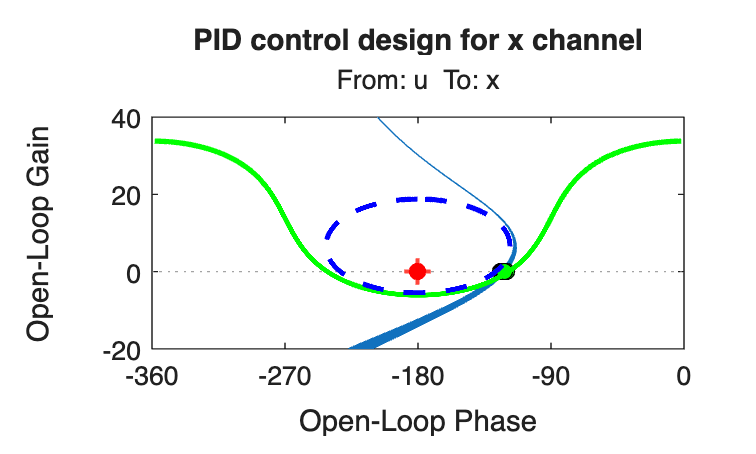


G_PID_x = (K*(1 + s/alpha)*(1 + T_i*s))/(s*T_i*(1 + s/beta));
G_PID_x.InputName = {'e'};
G_PID_x.OutputName = {'u'};

% bodemag(G_PID_x)

L_PID_x = connect(G_PID_x, P_PD_x, {'e'}, {'x'});
L_PID_x.InputName = 'u';
L_PID_x.OutputName = 'x';

% bode(L_PID_x)

% figure, clf, hold on
% bodemag((P.NominalValue(1,1,1,1)/A),{10^(-5), 10^2})
% bodemag(1+L_PID_x.NominalValue,{10^(-5), 10^2})
% xline(wp_d, '--')
% xline(wp_d/10, '-.')
% legend('P/A', '1+L', 'w_1', 'w_1/10','Location','southwest')
% hold off
% 
% figure, clf, hold on
% bodemag((A),{10^(-5), 10^5})
% bodemag(P.NominalValue(1,1,1,1)/(1+L_PID_x.NominalValue),{10^(-5), 10^5})
% xline(wp_d, '--')
% xline(wp_d/10, '-.')
% legend('A', 'P/(1+L)', 'w_1', 'w_1/10','Location','southwest')
% hold off

figure,clf,hold on

M = [1/Ma 1/Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2,DisplayName='Ma' )
    elseif( k==2 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2,DisplayName='Mb' )
    % elseif( k==3 )
    %     plot( phi_H(2:end-1),mag_H(2:end-1),'-r',LineWidth=2,DisplayName='Md1' )
    % else
    %     plot( phi_H(2:end-1),mag_H(2:end-1),'--k',LineWidth=2,DisplayName='Md2' )
    end
end

plot(-180,0,'ro',MarkerFaceColor='r',DisplayName='CriticalPoint')


for i = 1:20
    sys_i = usample(L_PID_x);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o','MarkerFaceColor','g','MarkerEdgeColor','k')
end

nichols(L_PID_x,{0.01,500});
xlim([-360,0]),ylim([-20 40])
title('PID control design for x channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off



G_PID_x_DT = c2d(G_PID_x,Ts_c)


G_PID_x_DT =
 
  From input "e" to output "u":
  26.59 z^2 - 53.15 z + 26.56
  ---------------------------
    z^2 - 1.882 z + 0.8818
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PID_x)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PID_x, 1), opts);

Y controller design

Ts = 3;
OS = 15;

lead = 82; % deg 81
K = 0.14; %0.14
T_i = 12; %12

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1231

beta = w_max^2/alpha

beta = 25.1682


G_PID_y = (K*(1 + s/alpha)*(1 + T_i*s))/(s*T_i*(1 + s/beta));
G_PID_y.InputName = {'e'};
G_PID_y.OutputName = {'u'}


G_PID_y =
 
  From input "e" to output "u":
  42.28 s^2 + 8.727 s + 0.4336
  ----------------------------
      1.477 s^2 + 37.17 s
 
Continuous-time transfer function.


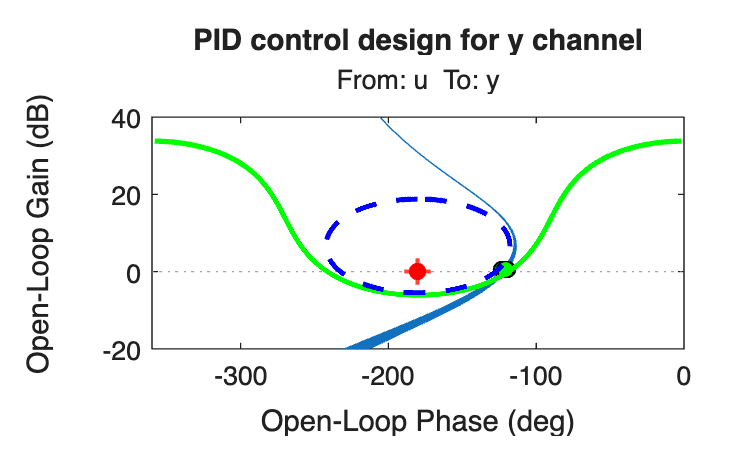


% bodemag(G_PID_y)

L_PID_y = connect(G_PID_y, P_PD_y, {'e'}, {'y'});
L_PID_y.InputName = 'u';
L_PID_y.OutputName = 'y';

% bodemag(L_PID_y)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PID_y);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PID_y,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PID control design for y channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PID_y_DT = c2d(G_PID_y,Ts_c)


G_PID_y_DT =
 
  From input "e" to output "u":
  28.63 z^2 - 57.23 z + 28.6
  --------------------------
    z^2 - 1.882 z + 0.8818
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PID_y)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PID_y, 1), opts);

z controller design

Ts = 3;
OS = 15;

lead = 74; % deg
K = 0.45;
T_i = 7.5;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.2473

beta = w_max^2/alpha

beta = 12.5226


G_PID_z = (K*(1 + s/alpha)*(1 + T_i*s))/(s*T_i*(1 + s/beta))


G_PID_z =
 
  42.26 s^2 + 16.09 s + 1.394
  ---------------------------
      1.855 s^2 + 23.23 s
 
Continuous-time transfer function.


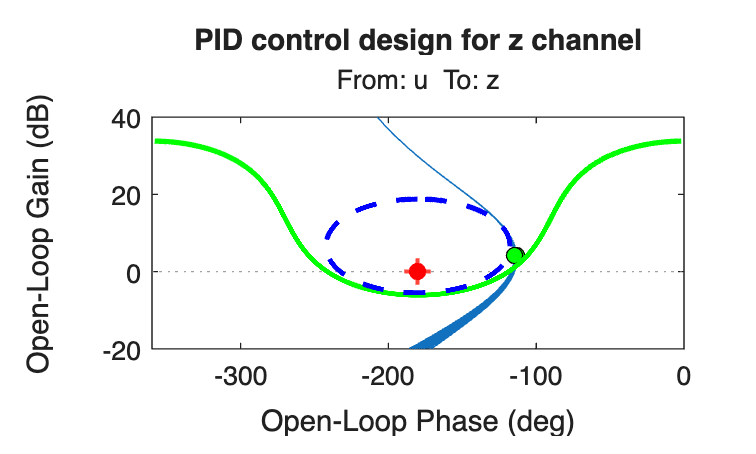

G_PID_z.InputName = {'e'};
G_PID_z.OutputName = {'u'};

% bodemag(G_PID_z)

L_PID_z = connect(G_PID_z, P_z, {'e'}, {'z'});
L_PID_z.InputName = 'u';
L_PID_z.OutputName = 'z';

% bodemag(L_PID_z)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PID_z);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PID_z,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PID control design for z channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PID_z_DT = c2d(G_PID_z,Ts_c)


G_PID_z_DT =
 
  From input "e" to output "u":
  22.78 z^2 - 45.52 z + 22.74
  ---------------------------
    z^2 - 1.939 z + 0.9393
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PID_z)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PID_z, 1), opts);


## PD+ESO Control design

Simulate = false;


x and y specs

Ts = 3; % s
OS = 15; % %

% k_d =0 ;
% wn_d = 0.24;
% zeta_d =1.3;% 1/sqrt(2);
% 
% D_Ts = 10;
% D_max = 30;
% 
% A = (2*k_d*wn_d*zeta_d*s)/(s^2 + 2*wn_d*zeta_d*s + wn_d^2)
% [~,wp_d] = getPeakGain(A);
% figure, clf, hold on
% config = RespConfig("Amplitude",0.01);
% [y,t]=step(A,config);
% plot(t,y)%*180/pi)
% yline(D_max*pi/180,'--')
% xline(D_Ts,'--')
% hold off

x controller design

lead = 78; % deg 82
K = 0.19; % 0.16

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound
% Md1 = abs(freqresp(P.NominalValue(1,1,1,1),wp))/abs(freqresp(A,wp_d));
% Md2 = abs(freqresp(P.NominalValue(1,1,1,1),wp))/abs(freqresp(A,wp_d/10));

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1850

beta = w_max^2/alpha

beta = 16.7447

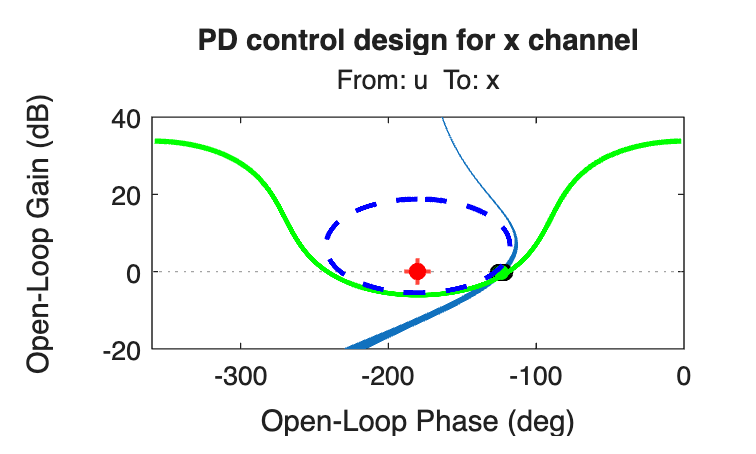


G_PD_x = (K*(1 + s/alpha))/(1 + s/beta);
G_PD_x.InputName = {'e'};
G_PD_x.OutputName = {'u'};

% bodemag(G_PD_x)

L_PD_x = connect(G_PD_x, P_PD_x, {'e'}, {'x'});
L_PD_x.InputName = 'u';
L_PD_x.OutputName = 'x';

% bode(L_PD_x)

% figure, clf, hold on
% bodemag((P.NominalValue(1,1,1,1)/A),{10^(-5), 10^2})
% bodemag(1+L_PD_x.NominalValue,{10^(-5), 10^2})
% xline(wp_d, '--')
% xline(wp_d/10, '-.')
% legend('P/A', '1+L', 'w_1', 'w_1/10','Location','southwest')
% hold off
% 
% figure, clf, hold on
% bodemag((A),{10^(-5), 10^5})
% bodemag(P.NominalValue(1,1,1,1)/(1+L_PD_x.NominalValue),{10^(-5), 10^5})
% xline(wp_d, '--')
% xline(wp_d/10, '-.')
% legend('A', 'P/(1+L)', 'w_1', 'w_1/10','Location','southwest')
% hold off

figure,clf,hold on

M = [1/Ma 1/Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2,DisplayName='Ma' )
    elseif( k==2 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2,DisplayName='Mb' )
    % elseif( k==3 )
    %     plot( phi_H(2:end-1),mag_H(2:end-1),'-r',LineWidth=2,DisplayName='Md1' )
    % else
    %     plot( phi_H(2:end-1),mag_H(2:end-1),'--k',LineWidth=2,DisplayName='Md2' )
    end
end

plot(-180,0,'ro',MarkerFaceColor='r',DisplayName='CriticalPoint')


for i = 1:20
    sys_i = usample(L_PD_x);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o','MarkerFaceColor','g','MarkerEdgeColor','k')
end
nichols(L_PD_x,{0.01,500});
xlim([-360,0]),ylim([-20 40])
title('PD control design for x channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])

hold off


% config = RespConfig("Amplitude",5);
% step(feedback(P(1,1,1,1).NominalValue*G_PD_x,1),config)
% 
% config = RespConfig("Amplitude",0.01);
% step(feedback(P(1,1,1,1).NominalValue,-G_PD_x,+1), config);

G_PD_x_DT = c2d(G_PD_x,Ts_c)


G_PD_x_DT =
 
  From input "e" to output "u":
  17.2 z - 17.18
  --------------
    z - 0.9197
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PD_x)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PD_x, 1), opts);

Y controller design

Ts = 3;
OS = 15;

lead = 78; % deg 81
K = 0.2; %0.14

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1850

beta = w_max^2/alpha

beta = 16.7447


G_PD_y = (K*(1 + s/alpha))/(1 + s/beta);
G_PD_y.InputName = {'e'};
G_PD_y.OutputName = {'u'}


G_PD_y =
 
  From input "e" to output "u":
  3.349 s + 0.6195
  ----------------
  0.185 s + 3.097
 
Continuous-time transfer function.


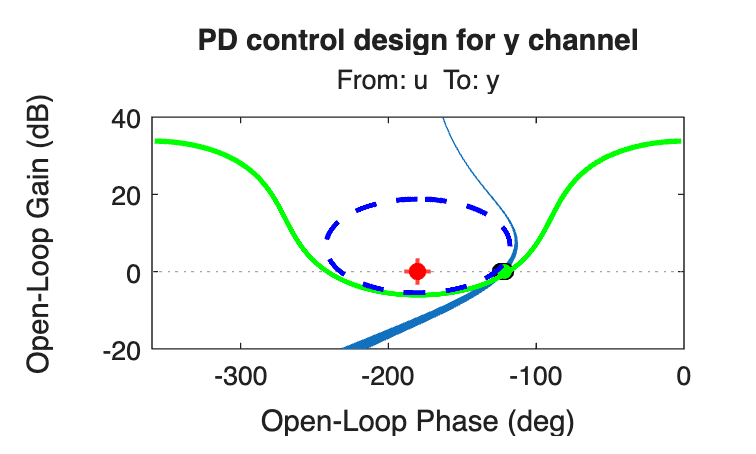


% bodemag(G_PD_y)

L_PD_y = connect(G_PD_y, P_PD_y, {'e'}, {'y'});
L_PD_y.InputName = 'u';
L_PD_y.OutputName = 'y';

% bodemag(L_PD_y)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PD_y);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PD_y,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PD control design for y channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PD_y_DT = c2d(G_PD_y,Ts_c)


G_PD_y_DT =
 
  From input "e" to output "u":
  18.1 z - 18.09
  --------------
    z - 0.9197
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PD_y)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PD_y, 1), opts);

z controller design

Ts = 3;
OS = 15;

lead = 68; % deg
K = 0.5;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.3421

beta = w_max^2/alpha

beta = 9.0541

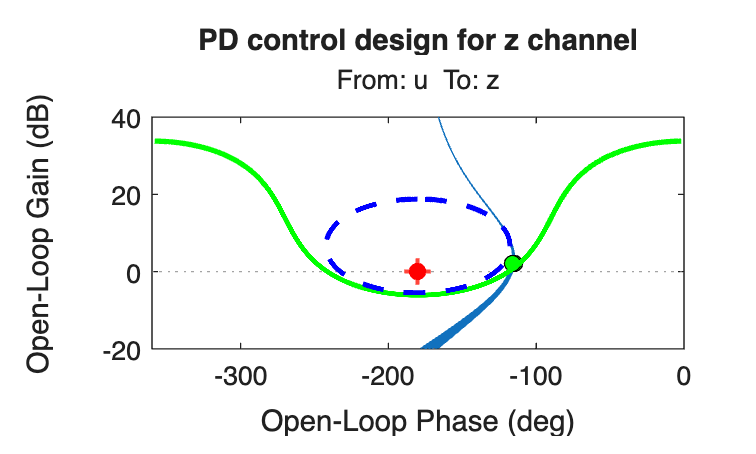


G_PD_z = (K*(1 + s/alpha))/(1 + s/beta);
G_PD_z.InputName = {'e'};
G_PD_z.OutputName = {'u'};

% bodemag(G_PD_z)

L_PD_z = connect(G_PD_z, P_z, {'e'}, {'z'});
L_PD_z.InputName = 'u';
L_PD_z.OutputName = 'z';

% bodemag(L_PD_z)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PD_z);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PD_z,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PD control design for z channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PD_z_DT = c2d(G_PD_z,Ts_c)


G_PD_z_DT =
 
  From input "e" to output "u":
  13.23 z - 13.21
  ---------------
    z - 0.9557
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PD_z)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PD_z, 1), opts);

ESO design

w_o_PDESO_pos = 3; % rad/s
b_0_x_PDESO = 1/m;
b_0_y_PDESO = 1/m;
b_0_z_PDESO = 1/m;

ONE = ones(1,1,'like',b_0_x_PDESO);

A_eso_CT =  [0 0 0 1 0 0 0 0 0;
             0 0 0 0 1 0 0 0 0;
             0 0 0 0 0 1 0 0 0;
             0 0 0 0 0 0 1 0 0;
             0 0 0 0 0 0 0 1 0;
             0 0 0 0 0 0 0 0 1;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0]*ONE;
B_eso_CT =  [0 0 0;
             0 0 0;
             0 0 0;
             b_0_x_PDESO 0 0;
             0 b_0_y_PDESO 0;
             0 0 b_0_z_PDESO;
             0 0 0;
             0 0 0;
             0 0 0;]*ONE;

C_eso_CT =  [1 0 0 0 0 0 0 0 0;
             0 1 0 0 0 0 0 0 0;
             0 0 1 0 0 0 0 0 0]*ONE;

L_CT =   [3*w_o_PDESO_pos   0           0;
            0       3*w_o_PDESO_pos^2     0;
            0       0           w_o_PDESO_pos^3;
            3*w_o_PDESO_pos   0           0;
            0       3*w_o_PDESO_pos^2     0;
            0       0           w_o_PDESO_pos^3;
            3*w_o_PDESO_pos   0           0;
            0       3*w_o_PDESO_pos^2     0;
            0       0           w_o_PDESO_pos^3;]*ONE;

ESO_CT = ss(A_eso_CT,B_eso_CT,C_eso_CT, zeros(3,3));

PDESO_ESO_pos_DT = c2d(ESO_CT, Ts_c);

vec_wo = 1:0.01:1+0.01*(6+3-1);
obs_poles = -w_o_PDESO_pos*vec_wo;
obs_poles = exp(obs_poles*Ts_c);

L_PDESO_pos_DT = place(PDESO_ESO_pos_DT.A',PDESO_ESO_pos_DT.A'*PDESO_ESO_pos_DT.C',obs_poles)';

% load("AttitudeControllers.mat")
% PosController="PDESO";
% AttController="PDESO";
% initVars
% J = usample(J_u);
% Tc_m = squeeze(usample(Tc_m_u,4));
% Td_m = squeeze(usample(Td_m_u,4));
% cmd2thrust = squeeze(usample(cmd2thrust_u,4));
% cmd2torque = squeeze(usample(cmd2torque_u,4));
% sim("QuadSimControl.slx");

## ADRC design

w_c_ADRC_pos = 0.7;
w_o_ADRC_pos = 6; % rad/s
b_0_x_ADRC = 1/m;
b_0_y_ADRC = 1/m;
b_0_z_ADRC = 1/m;

ONE = ones(1,1,'like',b_0_x_ADRC);

A_eso_CT =  [0 0 0 1 0 0 0 0 0;
             0 0 0 0 1 0 0 0 0;
             0 0 0 0 0 1 0 0 0;
             0 0 0 0 0 0 1 0 0;
             0 0 0 0 0 0 0 1 0;
             0 0 0 0 0 0 0 0 1;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0]*ONE;
B_eso_CT =  [0 0 0;
             0 0 0;
             0 0 0;
             b_0_x_ADRC 0 0;
             0 b_0_y_ADRC 0;
             0 0 b_0_z_ADRC;
             0 0 0;
             0 0 0;
             0 0 0;]*ONE;

C_eso_CT =  [1 0 0 0 0 0 0 0 0;
             0 1 0 0 0 0 0 0 0;
             0 0 1 0 0 0 0 0 0]*ONE;

L_CT =   [3*w_o_ADRC_pos   0           0;
            0       3*w_o_ADRC_pos^2     0;
            0       0           w_o_ADRC_pos^3;
            3*w_o_ADRC_pos   0           0;
            0       3*w_o_ADRC_pos^2     0;
            0       0           w_o_ADRC_pos^3;
            3*w_o_ADRC_pos   0           0;
            0       3*w_o_ADRC_pos^2     0;
            0       0           w_o_ADRC_pos^3;]*ONE;

ESO_CT = ss(A_eso_CT,B_eso_CT,C_eso_CT, zeros(3,3));

ADRC_ESO_pos_DT = c2d(ESO_CT, Ts_c);

vec_wo = 1:0.01:1+0.01*(6+3-1);
obs_poles = -w_o_ADRC_pos*vec_wo;
obs_poles = exp(obs_poles*Ts_c);

L_ADRC_pos_DT = place(ADRC_ESO_pos_DT.A',ADRC_ESO_pos_DT.A'*ADRC_ESO_pos_DT.C',obs_poles)';

% load("AttitudeControllers.mat")
% PosController="ADRC";
% AttController="PDESO";
% initVars
% 
% J = usample(J_u);
% Tc_m = squeeze(usample(Tc_m_u,4));
% Td_m = squeeze(usample(Td_m_u,4));
% cmd2thrust = squeeze(usample(cmd2thrust_u,4));
% cmd2torque = squeeze(usample(cmd2torque_u,4));
% sim("QuadSimControl.slx");

% save('PositionControllers.mat', 'Ts_c', ...
%         'G_PID_x_DT', 'G_PID_y_DT', 'G_PID_z_DT', ...
%         'b_0_x_PDESO', 'b_0_y_PDESO', 'b_0_z_PDESO','PDESO_ESO_pos_DT','L_PDESO_pos_DT','G_PD_x_DT', 'G_PD_y_DT', 'G_PD_z_DT',  ...
%         'b_0_x_ADRC', 'b_0_y_ADRC', 'b_0_z_ADRC','ADRC_ESO_pos_DT','L_ADRC_pos_DT','w_c_ADRC_pos');